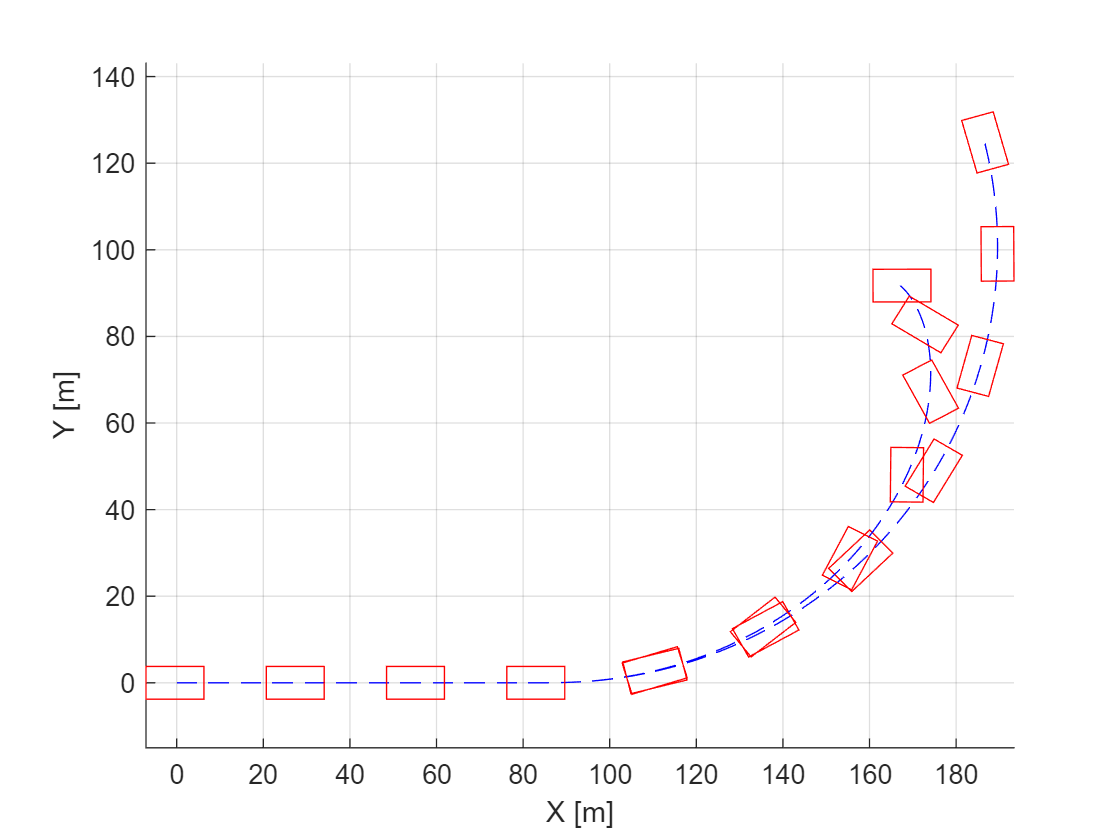

%% Vehicle path and orientation
% figure('Name','Path');
% figure(2)
hold on
plot(X,Y,'b--')
% plot(X_default65roll, Y_default65roll, 'b--')
axis equal;
grid on;
hold on;
xlabel('X [m]')
ylabel('Y [m]')

for i = 1:1/(sampleTime):length(psi)
    patch(X(i)+[X1(i) X2(i) X3(i) X4(i)], Y(i)+[Y1(i) Y2(i) Y3(i) Y4(i)],'red','facecolor','none','edgecolor','red');
%     patch(X(i)+[X1(i) X2(i) X3(i) X4(i)], Y(i)+[Y1(i) Y2(i) Y3(i) Y4(i)],'red','facecolor','none','edgecolor','red');
end
hold off

%% Yaw rate
% figure('Name','Yaw Rate');
% figure(1)
% subplot(2,4,3)
hold on
plot(t,wz*180/pi,t,delta.*vx/vehicleData.L*180/pi,'r--')
grid on;
ylabel('Yaw rate [deg/s]')
xlabel('Time [s]')
legend('Actual 0.65','Neutral Steer 0.65','Actual 0.45', 'Nerural Steer 0.45')